# **Mini Project 2: 3D Scanner**

#### **Alana Huitric and Maya Lum**

**This code is used to run the Arduino, collect 3D scan data while moving the scanner using a pan and tilt servo. The collected data is then processed and displayed. To use this code, change the Arduino port to match what it is in device manager, and make sure the pins of the IR sensor and servos match those in the 'setUp' function in the bottom section of the code.**

% Initial setup
clc
clear
[robotArduino, rawRangeIn, blinkLED, panServo, tiltServo] = setUp('COM6');
disp('Collecting Data')


% Create Calibration Data Manually
%distanceData = calibrationLoop(robotArduino,rawRangeIn,blinkLED);
%plot(distanceData(:,2), distanceData(:,1),'*');
%ff = createFit(distanceData(:,2), distanceData(:,1));

%This calibration data is taken from the specification sheet of the IR
%sensor. We also ran several trials where calibration data was manually
%inputted.
dataSheetCalibration = [15 2.75; 20 2.55; 30 2; 40 1.55; 50 1.25; 60 1.05; 70 0.9; 80 0.8; 90 0.7; 100 0.6; 110 0.55; 120 0.52; 130 0.5; 140 0.48; 150 0.49]

dataSheetCalibration =    15.0000    2.7500
   20.0000    2.5500
   30.0000    2.0000
   40.0000    1.5500
   50.0000    1.2500
   60.0000    1.0500
   70.0000    0.9000
   80.0000    0.8000
   90.0000    0.7000
  100.0000    0.6000


load("fitteddecaymodel.mat"); % fitted model for the data sheet

ff = fit(dataSheetCalibration(:,2),dataSheetCalibration(:,1),fittedmodel);

ff =      General model Power1:
     ff(x) = a*x^b
     Coefficients (with 95% confidence bounds):
       a =       60.79  (56.19, 65.4)
       b =      -1.117  (-1.241, -0.9919)

figure
hold on
x = linspace(.2,5);
y = fittedmodel.a*x.^(fittedmodel.b);

y =   366.7544  287.8110  235.8651  199.2152  172.0400  151.1259  134.5575  121.1241  110.0241  100.7059   92.7781   85.9553   80.0248   74.8247   70.2299   66.1420   62.4828   59.1893   56.2099   53.5026   51.0322   48.7694   46.6896   44.7716   42.9978   41.3526   39.8227   38.3967   37.0645   35.8172   34.6472   33.5476   32.5123   31.5359   30.6136   29.7412   28.9147   28.1307   27.3861   26.6779   26.0037   25.3610   24.7478   24.1621   23.6022   23.0663   22.5531   22.0610   21.5889   21.1357


plot(x,y)
plot(dataSheetCalibration(:,2),dataSheetCalibration(:,1),'*');
title('Fitted Curve and Raw Data');
xlabel('Voltage (V)');
ylabel('Distance (cm)');
hold off

%Now collect the scan data

Time for Trials


[numTests, trialData] = positionOverAngle(robotArduino, rawRangeIn, panServo, tiltServo, blinkLED)

Finished Collecting


numTests = 50

trialData =     0.8244         0         0
    0.8407         0    0.0204
    0.8309         0    0.0408
    0.8684         0    0.0612
    0.7348         0    0.0816
    0.7527         0    0.1020
    0.7071         0    0.1224
    0.6712         0    0.1429
    0.7022         0    0.1633
    0.6517         0    0.1837


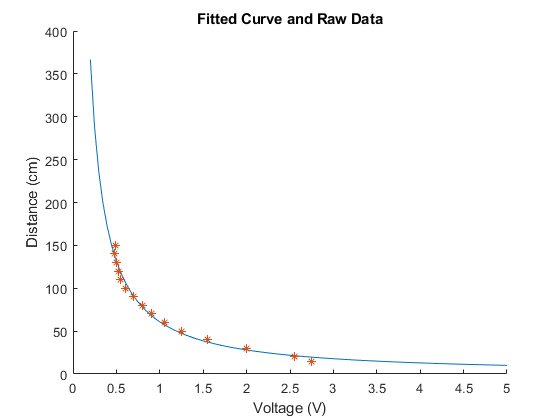


% Convert voltage to distance (cm) using calibration curve
distance = zeros(numTests,1);
voltage = trialData(:,1);
for i = 1:length(voltage)
    curr = (voltage(i));
    distance(i) = ff(curr);
    if distance(i) > 300
        distance(i) = 300; % Get rid of outliers due to exponential fitted curve
    end
end

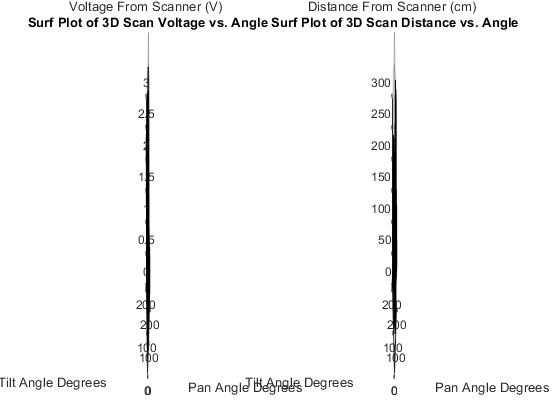


% Graph results
% Surf plots
panAnglesRad = trialData(:,2)*3.14;
tiltAnglesRad = trialData(:,3)*3.14;
figure
subplot(1,2,1)
tri=delaunay(trialData(:,2),trialData(:,3));
trisurf(tri,trialData(:,2)*180,trialData(:,3)*180,voltage)
title('3D Scan Voltage vs. Angle')
xlabel('Pan Angle Degrees')
ylabel('Tilt Angle Degrees')
zlabel('Voltage From Scanner (V)')
subplot(1,2,2)
trisurf(tri,trialData(:,2)*180,trialData(:,3)*180,distance)
title('3D Scan Distance vs. Angle')
xlabel('Pan Angle Degrees')
ylabel('Tilt Angle Degrees')
zlabel('Distance From Scanner (cm)')
hold off

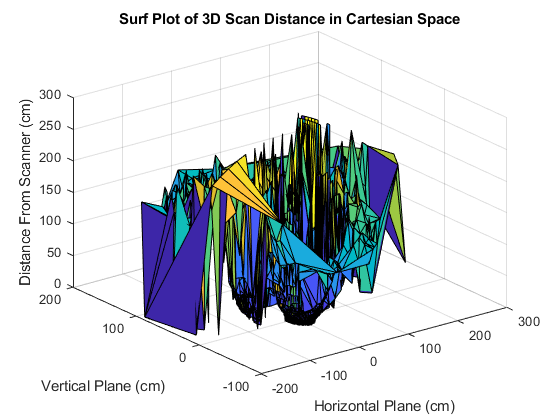

figure
[x,y,z] = sph2cart(panAnglesRad,tiltAnglesRad,distance);
tri = delaunay(x,y);
trisurf(tri, x, y, z)
title('3D Scan Distance in Cartesian Space') %This seems to have some issues
xlabel('Horizontal Plane (cm)')
ylabel('Vertical Plane (cm)')
zlabel('Distance From Scanner (cm)')

cartData = [distance panAnglesRad tiltAnglesRad]

cartData =    75.4260         0         0
   73.7956         0    0.0641
   74.7657         0    0.1282
   71.1722         0    0.1922
   85.7680         0    0.2563
   83.4909         0    0.3204
   89.5280         0    0.3845
   94.8828         0    0.4486
   90.2242         0    0.5127
   98.0668         0    0.5767


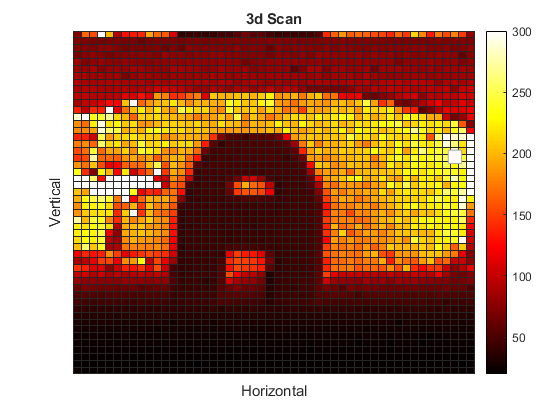

dataTable = array2table(cartData, 'VariableNames',{'Distance','Horizontal','Vertical'});
SCAN = heatmap(dataTable,"Horizontal","Vertical",'ColorVariable',"Distance","Title","3d Scan", 'ColorMap',hot);
SCAN.XDisplayLabels = nan(size(SCAN.XDisplayData));
SCAN.YDisplayLabels = nan(size(SCAN.YDisplayData));

%Heat Plots
figure
title('Surf Plot of 3D Scan Voltage in Cartesian Space')
xlabel('Horizontal Plane (cm)')
ylabel('Vertical Plane (cm)')
zlabel('Voltage From Scanner (V)')
cartData = [voltage panAnglesRad tiltAnglesRad]

cartData =     0.8244         0         0
    0.8407         0    0.0641
    0.8309         0    0.1282
    0.8684         0    0.1922
    0.7348         0    0.2563
    0.7527         0    0.3204
    0.7071         0    0.3845
    0.6712         0    0.4486
    0.7022         0    0.5127
    0.6517         0    0.5767


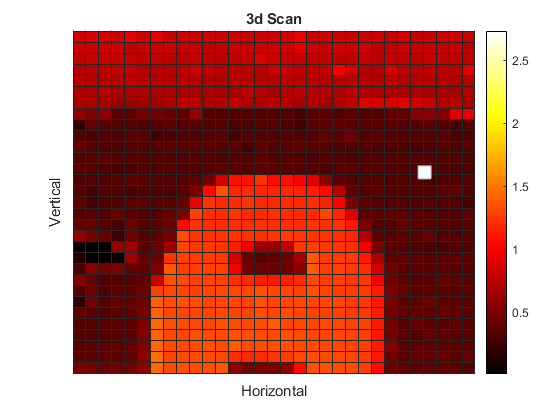

dataTable = array2table(cartData, 'VariableNames',{'Voltage','Horizontal','Vertical'});
SCAN = heatmap(dataTable,"Horizontal","Vertical",'ColorVariable',"Voltage","Title","3d Scan", 'ColorMap',hot);
SCAN.XDisplayLabels = nan(size(SCAN.XDisplayData));
SCAN.YDisplayLabels = nan(size(SCAN.YDisplayData));

figure
title('Surf Plot of 3D Scan Voltage in Cartesian Space')
xlabel('Horizontal Plane (cm)')
ylabel('Vertical Plane (cm)')
zlabel('Voltage From Scanner (V)')
cartData = [voltage x y]
dataTable = array2table(cartData, 'VariableNames',{'Voltage','Horizontal','Vertical'});
SCAN = heatmap(dataTable,"Horizontal","Vertical",'ColorVariable',"Voltage","Title","3d Scan", 'ColorMap',hot);
SCAN.XDisplayLabels = nan(size(SCAN.XDisplayData));
SCAN.YDisplayLabels = nan(size(SCAN.YDisplayData));

% Put pan and tilt servos back in neutral position.
writePosition(panServo, 0.5);
writePosition(tiltServo, 0.5);
clc
disp('Finished');

Finished


clear robotArduino

Function Block

function [robotArduino, rawRangeIn, blinkLED, panServo, tiltServo] = setUp(COMPORT) %setup code
    robotArduino = arduino(COMPORT, 'Uno', 'Libraries', 'Servo');

    blinkLED = 'D13'; %Optionally add an LED instead of print statements
    configurePin(robotArduino, blinkLED, 'DigitalOutput');

    rawRangeIn = 'A1'; %Attach IR sensor to this pin
    configurePin(robotArduino,rawRangeIn,'AnalogInput');
    
    panServo = servo(robotArduino, 'D9', 'MinPulseDuration', 10*10^-6,...
    'MaxPulseDuration', 1925*10^-6);
    tiltServo = servo(robotArduino, 'D11', 'MinPulseDuration', 10*10^-6,...
    'MaxPulseDuration', 1925*10^-6);
    writePosition(panServo, 0.5); % always start servo-command at 0.5
    writePosition(tiltServo, 0.5); % always start servo-command at 0.5
    pause(7.0); % wait for arduino to send stable PWM
end

% This function blinks an LED n number of times
%
%  @ params
% a     the arduino object
% LED   LED pin
% n     number of times to blink
function [] = Blink(a,LED,n)
        for bIndex = 1:n
            writeDigitalPin(a,LED,0);
            pause(0.2);
            writeDigitalPin(a,LED,1);
            pause(0.2);
        end
end

% This function returns the output voltage of the IR sensor
%
%  @ params
% robotArduino      the arduino object
% rawRangeIn        analog sensor pin
function rangeData = sensing(robotArduino, rawRangeIn)
    pause(0.01)
    rangeData = readVoltage(robotArduino, rawRangeIn);
end

% This function creates an array of voltage and input distance data that
% can be then graphed and turned into a calibration curve. The user must
% manually move an object a measured distance away and input the distance
% when prompted. The first distance is collected immediately after being
% asked for the number of tests.
%
% @ params
% robotArduino      the arduino object
% rawRangeIn        analog sensor pin
% blinkLED          LED pin
function distanceData = calibrationLoop(robotArduino, rawRangeIn, blinkLED)
    numTests = input(['Enter number of tests']);
    clc;
    distanceData = zeros(numTests, 2);
    r = rateControl(0.25);
    reset(r);  
    index = 1;                    
    while(index < numTests+1)      
        rangeData = sensing(robotArduino, rawRangeIn);
        distanceData(index,1) = input('Enter distance(cm): ');
        gtest = input('Move to new distance then hit enter', 's');
        distanceData(index,2) = rangeData;
        Blink(robotArduino,blinkLED,1);
        waitfor(r);                     % wait for loop cycle to complete
        index = index+1;    % increment loop
    end
end

% This function plots the calibration data created manually, but does not
% add a calibration curve. This was used for earlier testing rather than
% the final project.
%
% @ params
% distanceData      output of the calibrationLoop
function plotCalibrationData(distanceData)
    % Plot and store command postion data vs. actual postion
    plot(distanceData(:,1), distanceData(:,2), '*')
    xlabel('Actual position')
    ylabel('Measured Voltage')
    hold off 
end

% This function collects analog sensor data over an inputted number of
% trials. This was also used earlier on in testing rather than the final
% product.
%
% @ params
% robotArduino      arduino object
% rawRangeIn        analog sensor pin
% blinkLED          LED pin
function [numTests, trialData] = positionOverTrials(robotArduino, rawRangeIn, blinkLED)
    numTests = input(['Enter number of tests for trial']);
    trialData = zeros(numTests,1);
    index = 1;
    while(index < numTests + 1)
        rangeData = sensing(robotArduino, rawRangeIn);
        trialData(index) = rangeData;
        Blink(robotArduino,blinkLED,1);
        pause(.2)
        index = index + 1;
    end
    disp('Finished Collecting') 
end

% This function runs the panning and tilting code for the two servos while
% collecting data at every position. When prompted to enter the number of
% tests for the trial, the trial will be nxn samples.
%
% @ params
% robotArduino      arduino object
% rawRangeIn        analog sensor pin
% panServo          pan servo pin
% tiltServo         tilt servo pin
% blinkLED          LED pin
function [numTests, trialData] = positionOverAngle(robotArduino, rawRangeIn, panServo, tiltServo, blinkLED)
    numTests = input(['Enter number of tests for trial']);
    trialData = zeros(numTests,3);
    angles = linspace(0,1,numTests);
    index = 1;
    for i = 1 : numTests
        writePosition(panServo, angles(i));
        pause(0.2);
        for j = 1 : numTests
            writePosition(tiltServo, angles(j));
            pause(0.2);
            %rangeData = sensing(robotArduino, rawRangeIn); %non averaged
            %value
            rdat1 = (sensing(robotArduino, rawRangeIn));
            rdat2 = (sensing(robotArduino, rawRangeIn));
            rdat3 = (sensing(robotArduino, rawRangeIn));
            rangeData = mean([rdat1 rdat2 rdat3]); %averaged to reduce noise
            trialData(index,:,:) = [rangeData angles(i) angles(j)];
            Blink(robotArduino, blinkLED, 1);
            index = index + 1;
        end
    end
    disp('Finished Collecting') 
end
